## Specify Hamiltonian

obs = observable(["YZ" "ZI" "ZZ" "XX"], [0.3980, -0.3980, 0.3980, 0.1810]);
H = getMatrix(obs)

H =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.3980i   0.1810 + 0.0000i
   0.0000 + 0.0000i  -0.7960 + 0.0000i   0.1810 + 0.0000i   0.0000 + 0.3980i
   0.0000 + 0.3980i   0.1810 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.1810 + 0.0000i   0.0000 - 0.3980i   0.0000 + 0.0000i   0.7960 + 0.0000i


## **Calculating the lowest eigenvalue of the Hamiltonian matrix classically for reference**

eigenvalues = min(eig(H))

eigenvalues = -0.9406

## Setting parameters for an ansatz

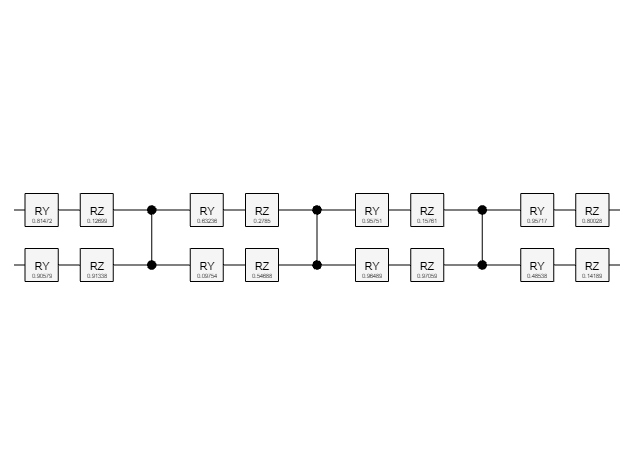

numQubits = 2;

% Number of repeated entangling blocks
ansatzDepth = 8;

% Number of learnable angles for the ansatz circuit
numAngles = numQubits*(ansatzDepth);

% Plot the ansatz with arbitrary angles to view its structure
randAnsatz = Efficient_SU2(rand(numAngles, 1), numQubits);
plot(randAnsatz)

## Define Optimizer and Determining Optimal Angles (or Gate Parameters)

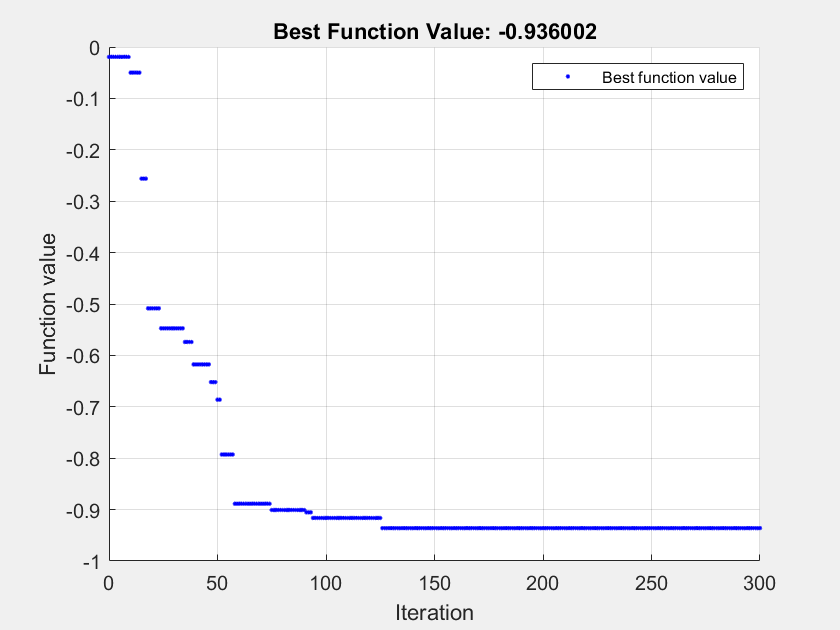

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


objFcn = @(theta) VQE(theta, obs);
lb = repmat(-pi, numAngles, 1); 
ub = repmat(pi, numAngles, 1);
options = optimoptions("surrogateopt", "MaxFunctionEvaluations",300);
[optAngles, fval] = surrogateopt(objFcn,lb,ub,[],[],[],[],[],options);

## Execute the ansatz on the MATLAB Simulator using the optimized angles.

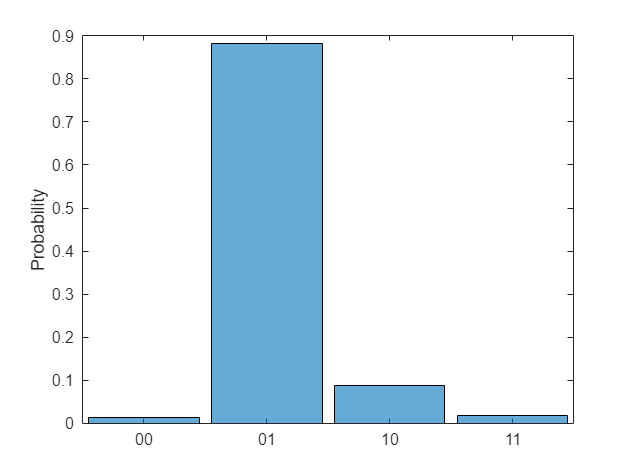

optAnsatz = Efficient_SU2(optAngles, numQubits);
sv = simulate(optAnsatz);
figure
histogram(sv)

## Execute the ansatz on the IonQ hardware hosted on AWS using the optimized angles.

reg = "us-east-1";
bucketPath = "s3://amazon-braket-mathworks/doc-example";
device = quantum.backend.QuantumDeviceAWS("Aria 1",Region=reg,S3Path=bucketPath);

Error using quantum.internal.aws.searchDevices
Failed to search devices.  Reason:
Unable to parse ExceptionName: ExpiredTokenException Message: The security token included in the request is expired

Error in quantum.internal.aws.quickListDevices (line 22)
    devs = quantum.internal.aws.searchDevices(regions(r));

Error in 

task = run(optAnsatz, device, NumShots = 100)
wait(task)
result = fetchOutput(task);
histogram(result)

## **Functions used in the notebook**

function value = VQE(angles, obs)  
ansatz = Efficient_SU2(angles,2);
qState = simulate(ansatz);
value = estimate(qState, obs, NumShots=1000);
end

function ansatz = Efficient_SU2(angles, numQubits)

    entgBlk = czGate(1:numQubits-1, 2:numQubits);
    angles = reshape(angles, numQubits, []);
    
    gates = [ryGate(1:numQubits, angles(:,1)); rzGate(1:numQubits, angles(:,2))];
    for p = 3:2:size(angles, 2)
    gates = [gates; entgBlk; ryGate(1:numQubits, angles(:,p)); rzGate(1:numQubits, angles(:,p+1))];
    end
    
    ansatz = quantumCircuit(gates);
end